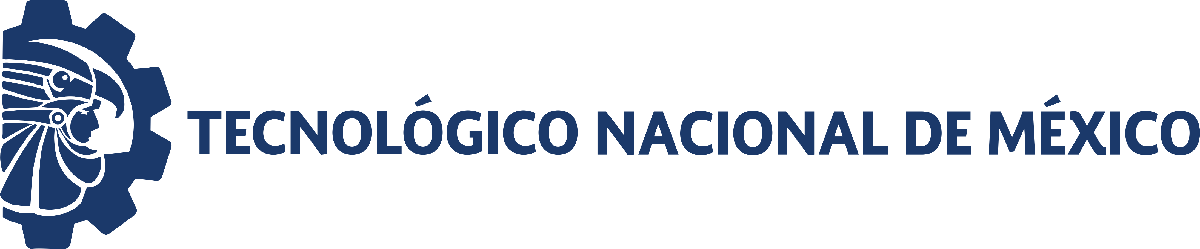                                 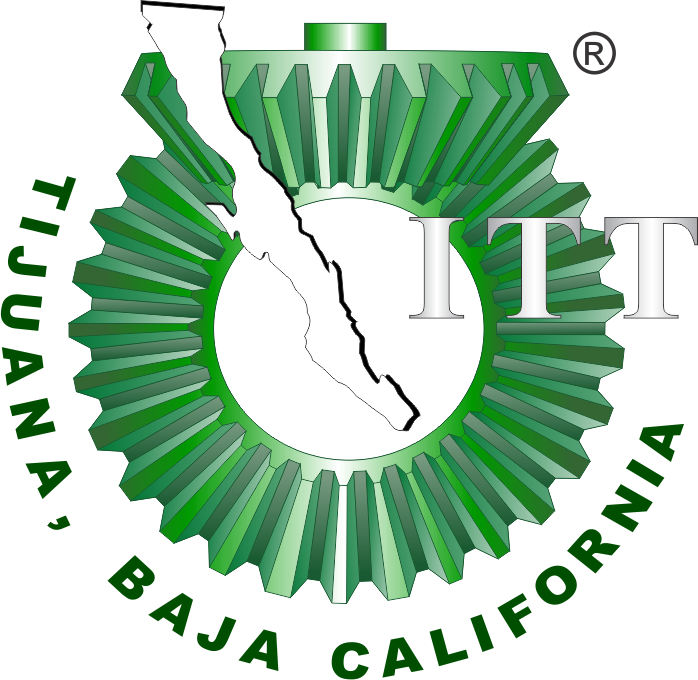

# Práctica 3: Muscoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Ian Enrique Estrada Castillo

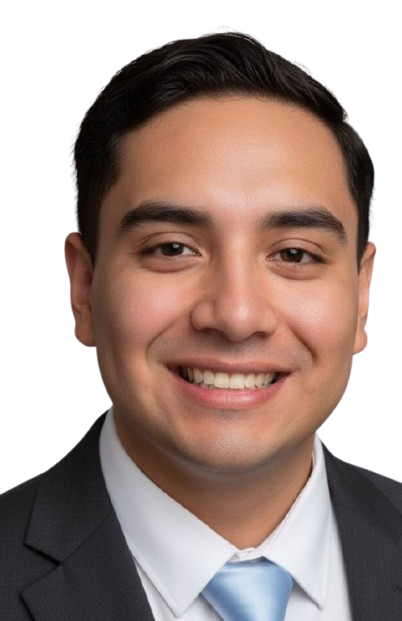

Número de control: 22211753

Correo institucional: l22211753**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

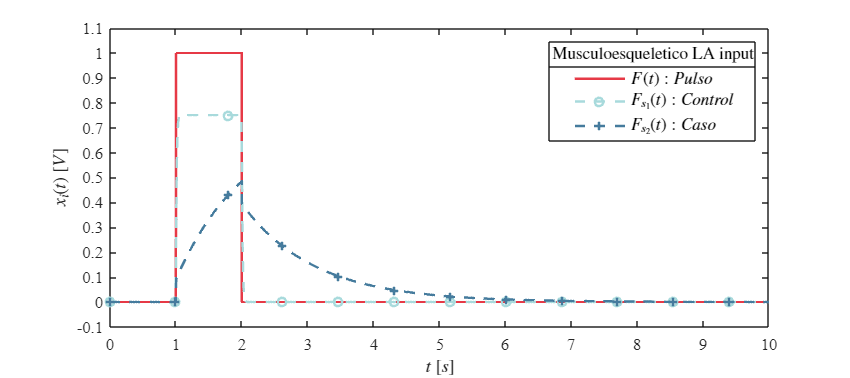

clc; clear; close all; warning('off','all')
tend = '10';
file = 'SistemaA';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
Signal='Musculoesqueletico LA';
Signal2='Musculoesqueletico LC';
set_param('SistemaA/F(s)','Amplitude','1');
set_param('SistemaA/F(s)','Period','10');
set_param('SistemaA/F(s)','PulseWidth','10');
set_param('SistemaA/F(s)','PhaseDelay','1');

x= sim(file,parameters);
plotsignals(x.t, x.F, x.Fs1, x.Fs2, Signal);

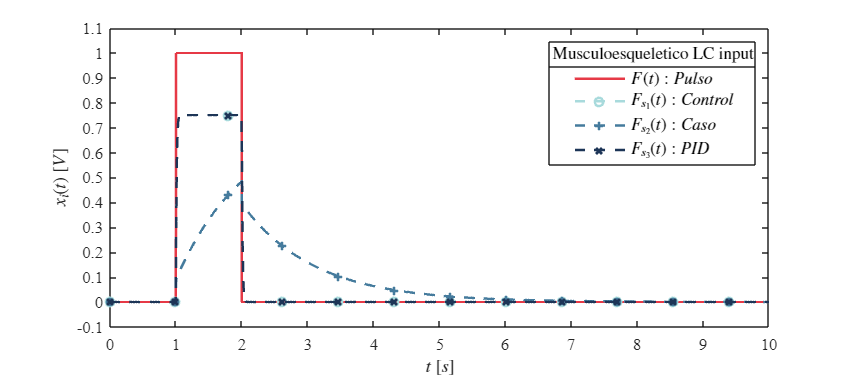

plotsignals2(x.t, x.F, x.Fs1, x.Fs2, x.Fs3, Signal2);

## Función: Respuesta a las señáles

function plotsignals(t,F,Fs1,Fs2,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'LineWidth',1.5); 
    L = legend('$F(t):Pulso$','$F_{s_1}(t):Control$','$F_{s_2}(t):Caso$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
       
        if Signal == "Musculoesqueletico LA"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks(-0.1:0.1:10);
        end

    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

end

function plotsignals2(t,F,Fs1,Fs2,Fs3,Signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',t,Fs3,'--x',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(4), 'LineWidth',1.5); 
    L = legend('$F(t):Pulso$','$F_{s_1}(t):Control$','$F_{s_2}(t):Caso$','$F_{s_3}(t):PID$');
    set(L,'Interpreter','Latex','FontSize',10);
    title(L,[Signal2,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

        if Signal2 == "Musculoesqueletico LC"
        xlim([0,10]); xticks(0:1:10);
        ylim([-0.1,1.1]); yticks(-0.1:0.1:10);
        end

    exportgraphics(gcf,[Signal2,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal2,'.png'],'ContentType','vector')

end
